dataDir = fullfile('Daten', 'FrogTraces'); 
trainDir = fullfile(dataDir, 'train');
testDir = fullfile(dataDir, 'test');
metaDataTrain = readtable(fullfile(trainDir, 'MetaDataTrain.csv'));
metaDataTest = readtable(fullfile(testDir, 'MetaDataTest.csv'));
nTrain = size(metaDataTrain, 1);
nTest = size(metaDataTest, 1);

img = imread(fullfile(trainDir, [metaDataTrain.Name{1} '.png']));
imSize = size(img);
pc = pcolor(linspace(-350, 350, imSize(1)), ...
   linspace(480, 520, imSize(2)), img);
pc.LineStyle='none';
title(sprintf('Breite: %.3f fs', metaDataTrain.RMSWidth(1)));
xlabel('\tau (fs)');
ylabel('Frequenz (THz)');

tainMat4 = zeros(imSize(1),imSize(2),1,nTrain);

for i = 1:nTrain
   img = imread(fullfile(trainDir, [metaDataTrain.Name{i} '.png']));
   trainMat4(:,:,1,i) = img;
end
% Zielgroessen aus Tabelle holen:
trainTarget = metaDataTrain.RMSWidth;

testMat4 = zeros(60,60,1, nTest);

for i = 1:nTest
   img = imread(fullfile(testDir, [metaDataTest.Name{i} '.png']));
   testMat4(:,:,1,i) = img;
end
testTarget = metaDataTest.RMSWidth;



load digitsNet
layers = net.Layers

layers =   15×1 Layer array with layers:

     1   'imageinput'    Image Input             28×28×1 images with 'zerocenter' normalization
     2   'conv_1'        2-D Convolution         8 3×3×1 convolutions with stride [1  1] and padding 'same'
     3   'batchnorm_1'   Batch Normalization     Batch normalization with 8 channels
     4   'relu_1'        ReLU                    ReLU
     5   'maxpool_1'     2-D Max Pooling         2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv_2'        2-D Convolution         16 3×3×8 convolutions with stride [1  1] and padding 'same'
     7   'batchnorm_2'   Batch Normalization     Batch normalization with 16 channels
     8   'relu_2'        ReLU                    ReLU
     9   'maxpool_2'     2-D Max Pooling         2×2 max pooling with stride [2  2] and padding [0  0  0  0]
    10   'conv_3'        2-D Convolution         32 3×3×16 convolutions

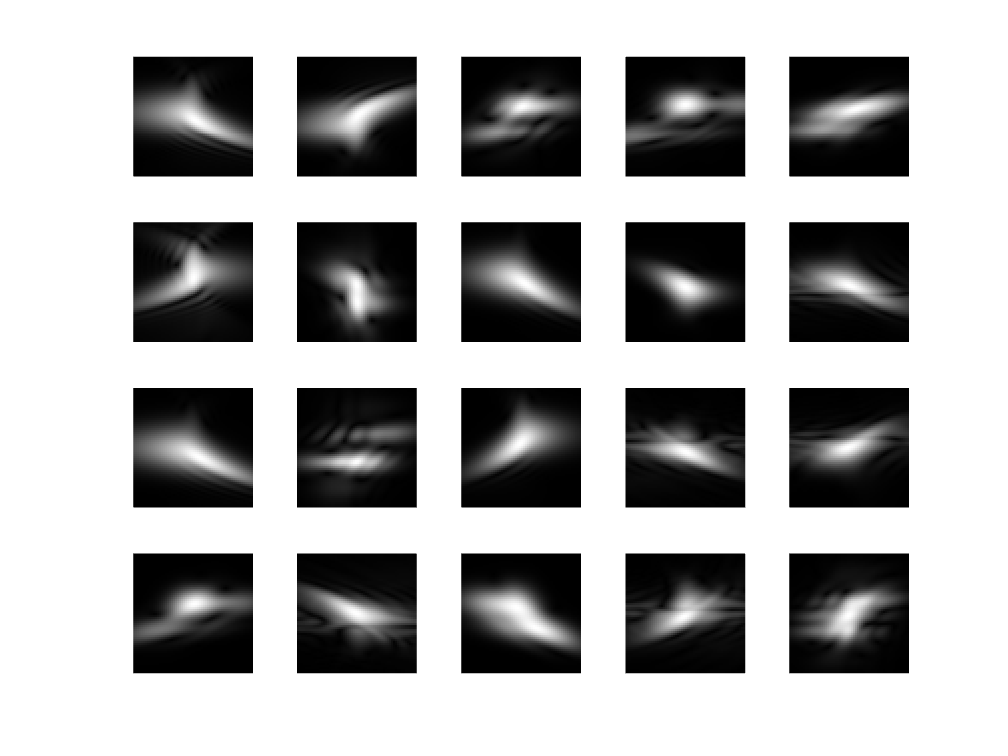

[XTrain,~,YTrain] = digitTrain4DArrayData;
[XValidation,~,YValidation] = digitTest4DArrayData;

XTrain = trainMat4;
YTrain = trainTarget;
numTrainImages = numel(YTrain);
figure
idx = randperm(numTrainImages,20);
for i = 1:numel(idx)
    subplot(4,5,i)    
    imshow(XTrain(:,:,:,idx(i)))
end

numResponses = 1;
layers = [
    imageInputLayer([60,60])
    layers(2:12)
    fullyConnectedLayer(numResponses)
    regressionLayer];

layers(2:7) = freezeWeights(layers(2:7));

lambda = 0.01; 
options = trainingOptions('adam',...
   'ValidationData', {testMat4, testTarget}, ...
   'MaxEpochs', 200, ...
   'MinibatchSize', 100, ...
   'L2Regularization', lambda, ...
   'Verbose', true, ...
   'Plots', 'none'); % training-progress'); 

net = trainNetwork(XTrain,YTrain,layers,options);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |       101.78 |        97.31 |    5179.7954 |    4735.0171 |          0.0010 |
|       3 |          50 |       00:00:21 |        14.04 |        15.75 |      98.5514 |     123.9817 |          0.0010 |
|       6 |         100 |       00:00:33 |        10.85 |        10.00 |      58.9011 |      50.0426 |          0.0010 |
|       9 |         150 |       00:00:45 |         7.94 |         7.60 |      31.5580 |   